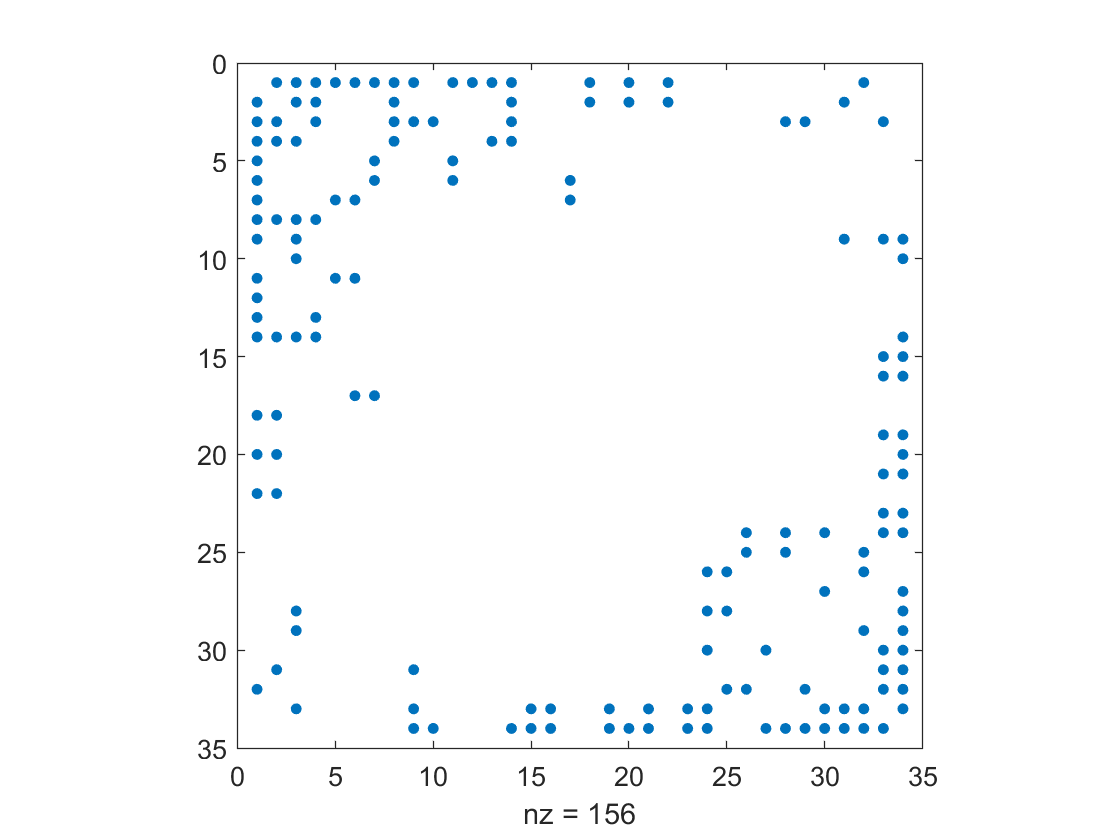

clear
load("spectralGraphPartitioning-karate.mat");
% load("spectraGraphPartitioning-polblogs.mat");
A = Problem.A;
spy(A);

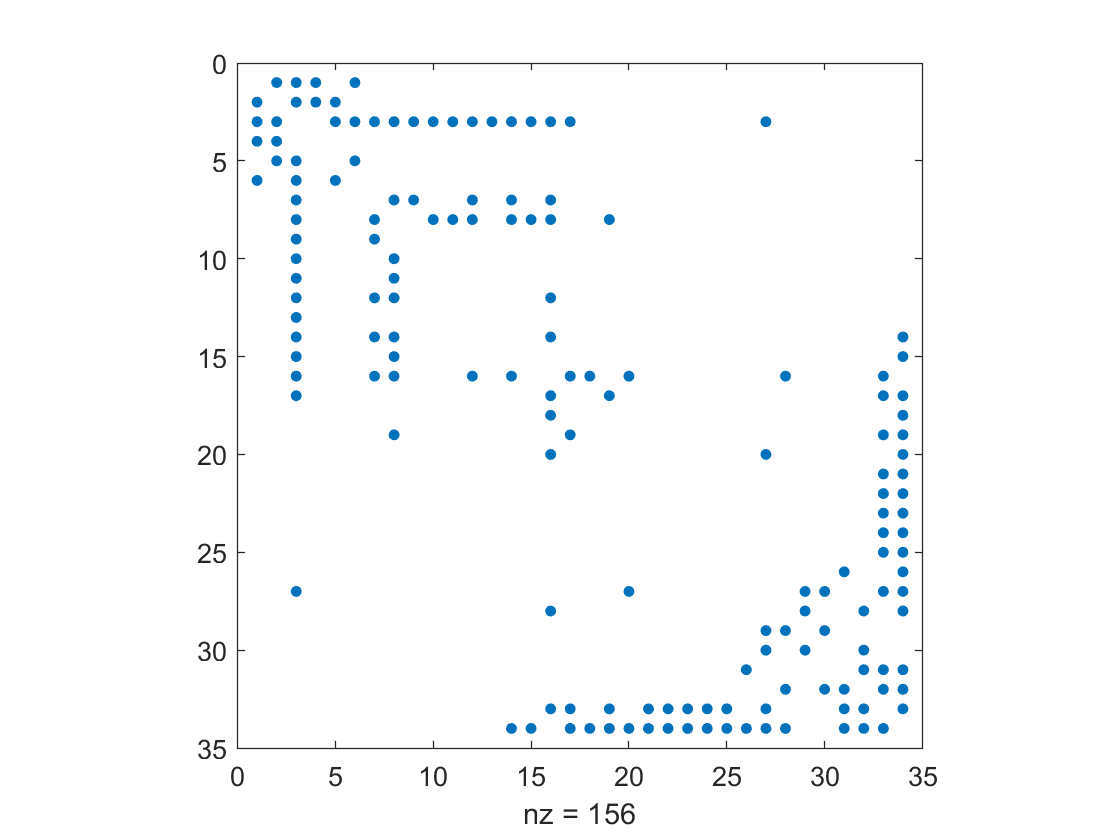


d = diag(A*A');
D = diag(d);

Dn = diag(d.^-(1/2));
L = full(D-A);
Ln = Dn*L*Dn;
[V,~] = eig(Ln);
Fiedler = V(:,2);

P = speye(length(Fiedler));
[~,p] = sort(Fiedler,'ascend');
P = P(p,:);
Ap = P*A*P';
spy(Ap);

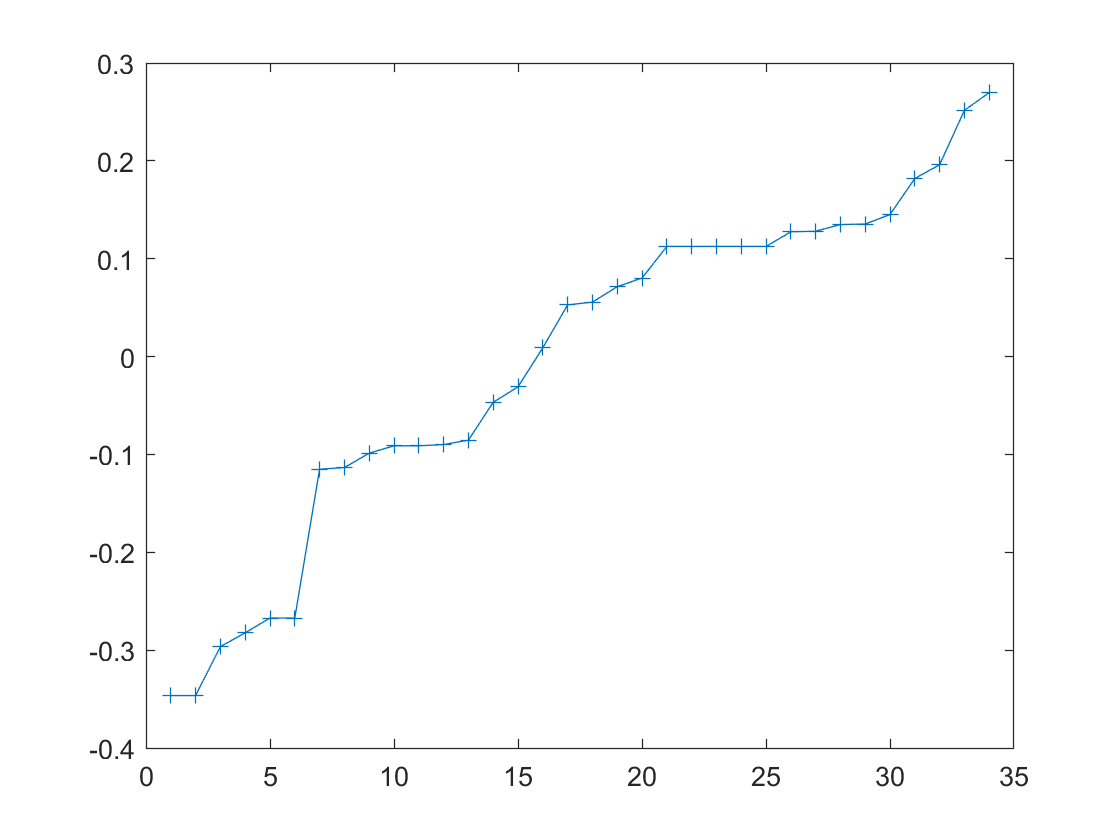


plot(Fiedler(p),'-+');

[~,n] = min(abs(Fiedler(p)))

n = 16

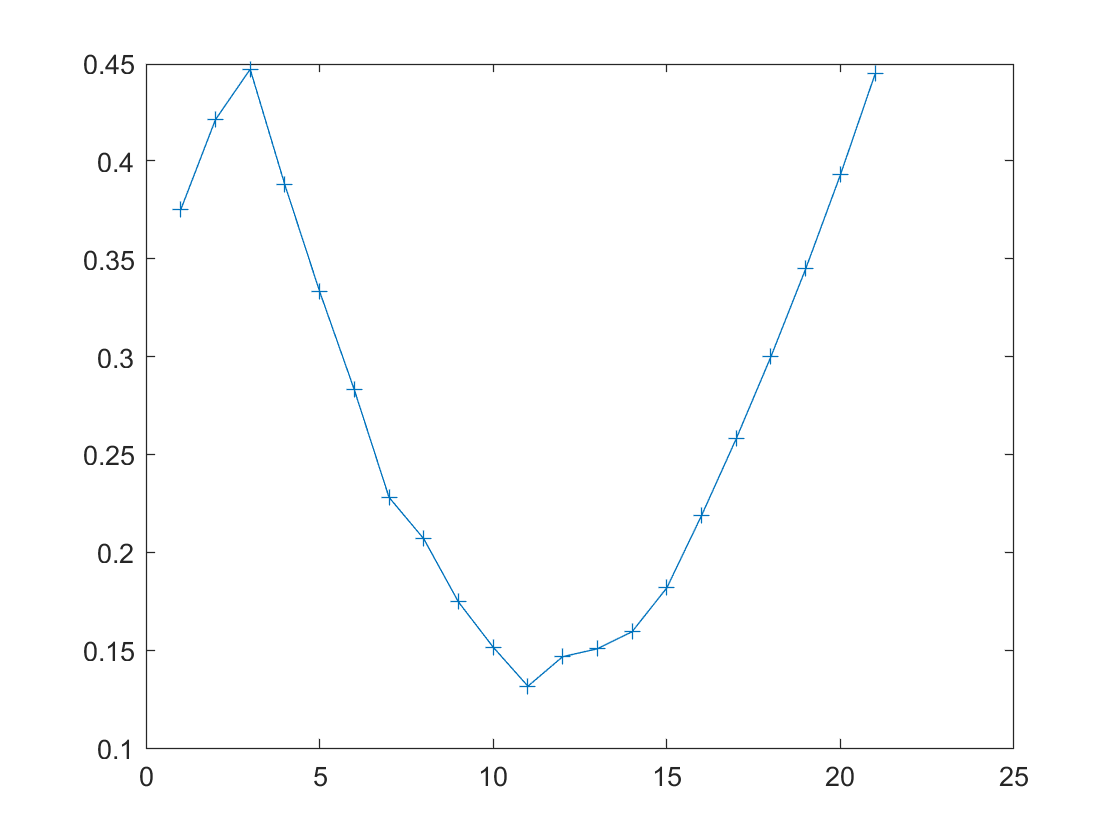

dp = P*d;

% This part might need a slight refactoring
% *********************************************
% Find lowest conductance
cond = zeros(21,2);
c = 1;
for nSplit=n-10:n+10
     % We save each cond value with the ind
     % of that value in the second col.
    cond(c,1) = sum(Ap(1:nSplit,nSplit+1:end),"all") /...
       min(sum(dp(1:nSplit)),sum(dp(nSplit+1:end)));
    cond(c,2) = nSplit;
    c = c+1;
end


plot(cond(:,1),'-+');

[~,minInd] = min(cond(:,1));
split = cond(minInd,2)

split = 16

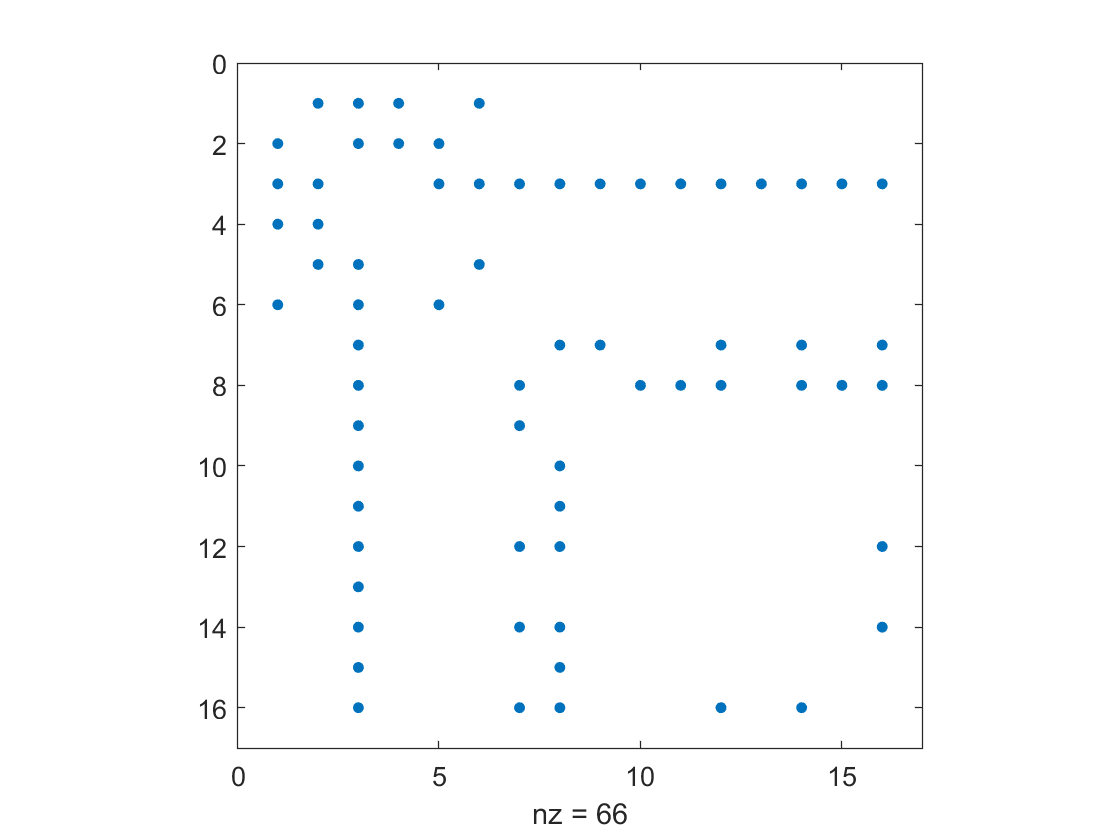

% **********************************************

A1 = Ap(1:split,1:split);
A2 = Ap(split+1:end,split+1:end);
spy(A1);

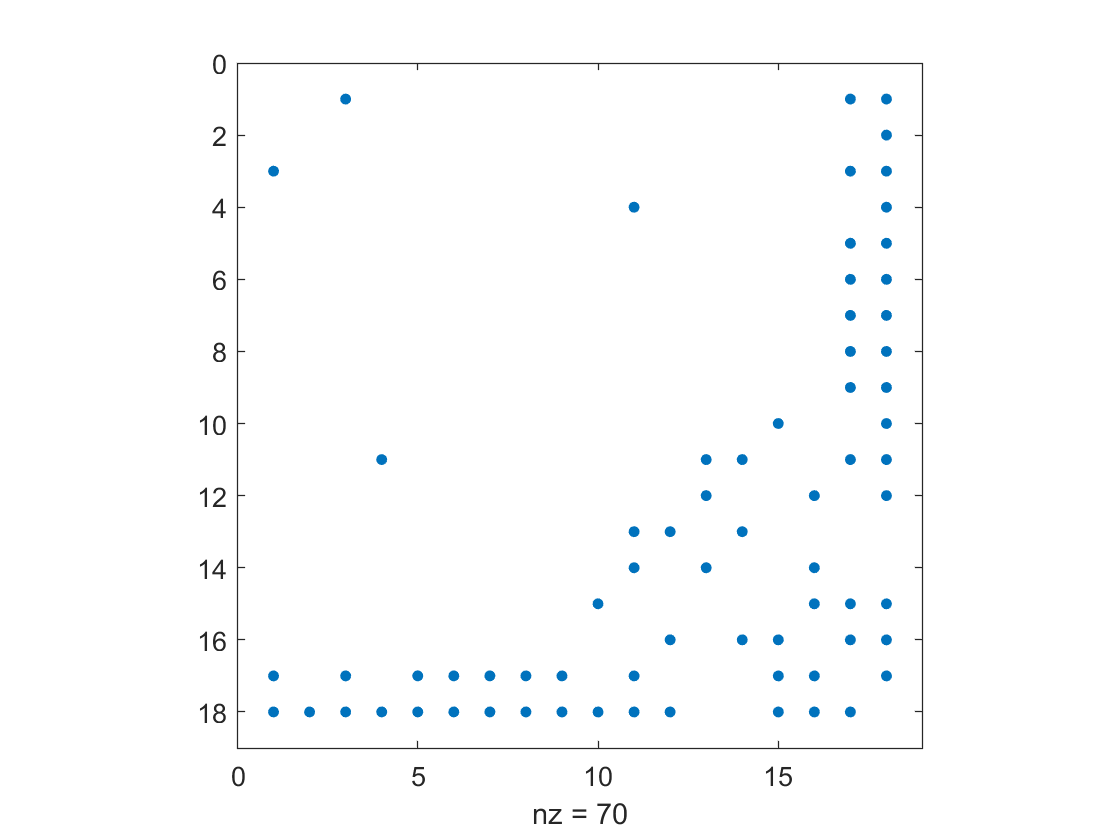

spy(A2);